# Risposte per i test Cap 6

### Interpolazione polinomiale (Lagrange)

    Qual è il grado del polinomio interpolante tale funzioneai nodi?

    Dato il numero n+1 di nodi, il grado del polinomio interpolante può essere 1,...,n. tendenzialmente se i nodi appartengono a una funzione che non è un polinomio allora il polinomio interpolante ha grado n

    Qual'è l'errore commesso dall'interpolazione?

f = @(x) x .* exp(-x) .* cos(4*x); % Funzione
a = -2; % Inizio intervall0
b = 2; % Fine intervallo
N = 9; % Numero nodi
n = N-1; % Grado polinomio 

xn = linspace(a,b,N);
yn = f(xn);
p = polyfit(xn,yn,n);

x = linspace(a,b,1000);
y = f(x);
u = polyval(p,x);
E = max(abs(u-y))

E = 5.6834

    Nodi equispaziati

a = -2; % Inizio intervall0
b = 2; % Fine intervallo
N = 9; % Numero nodi
n = N-1; % Grado polinomio 

xn = linspace(a,b,N);

    Nodi di Chebyshev-Gauss-Lobato

a = -2; % Inizio intervall0
b = 2; % Fine intervallo
N = 9; % Numero nodi
n = N-1; % Grado polinomio

k = 0:n;
xn_prov = cos(pi*k/n); % Nodi in [-1,1]
xn = (a+b)/2 + (b-a)/2*xn_prov;  % Nodi in [a,b]

### Interpolazione trigonometrica

### Interpolazione polinommiale a tratti composita

### Splines

### Metodi dei minimi quadratti lineari

    **Idea**: non interpolo in generale i dati ma cerco la funzione che meglio li approssima, utile se ho errori in essi

    **Implementazione**: usa polyfit e polyval con grado del polinomio < del grado del polinomio che passa per tutti i nodi

%% Esempio
f = @(x) cos(2 * pi * x);
a = -1;
b = 1;
n = 4; % Grado polinomio
N = 100; % Numero di nodi

xn = linspace(a,b,N);
yn = f(xn);
p = polyfit(xn,yn,n);
x = linspace(a,b,1000);
u = polyval(p,x);

    Somma degli scarti pesata

% Stai attento a usare solo le le y nei nodi
clear
f = @(x) cos(2 * pi * x);
a = -1;
b = 1;
n = 4; % Grado polinomio
N = 100; % Numero di nodi

xn = linspace(a,b,N);
yn = f(xn);
p = polyfit(xn,yn,n);
% x = linspace(a,b,1000);
% y = f(x);
% u = polyval(p,x)
un = polyval(p,xn);

% E = max(abs(u-y))

ssp = 1/N * sum(abs(yn-un).^2) % è lui

ssp = 0.1691

### Metodo dei minimi quadrati NON lineari

#### Metodo di Gauss-Newton

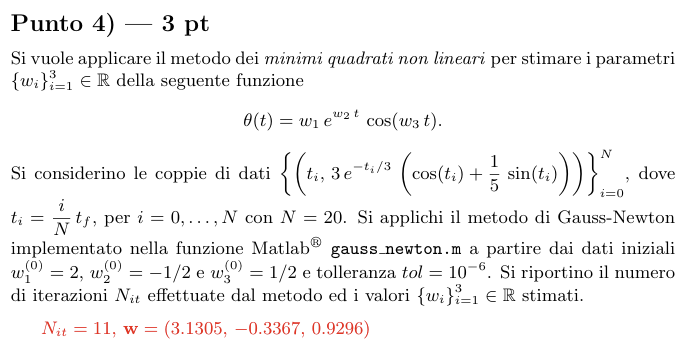

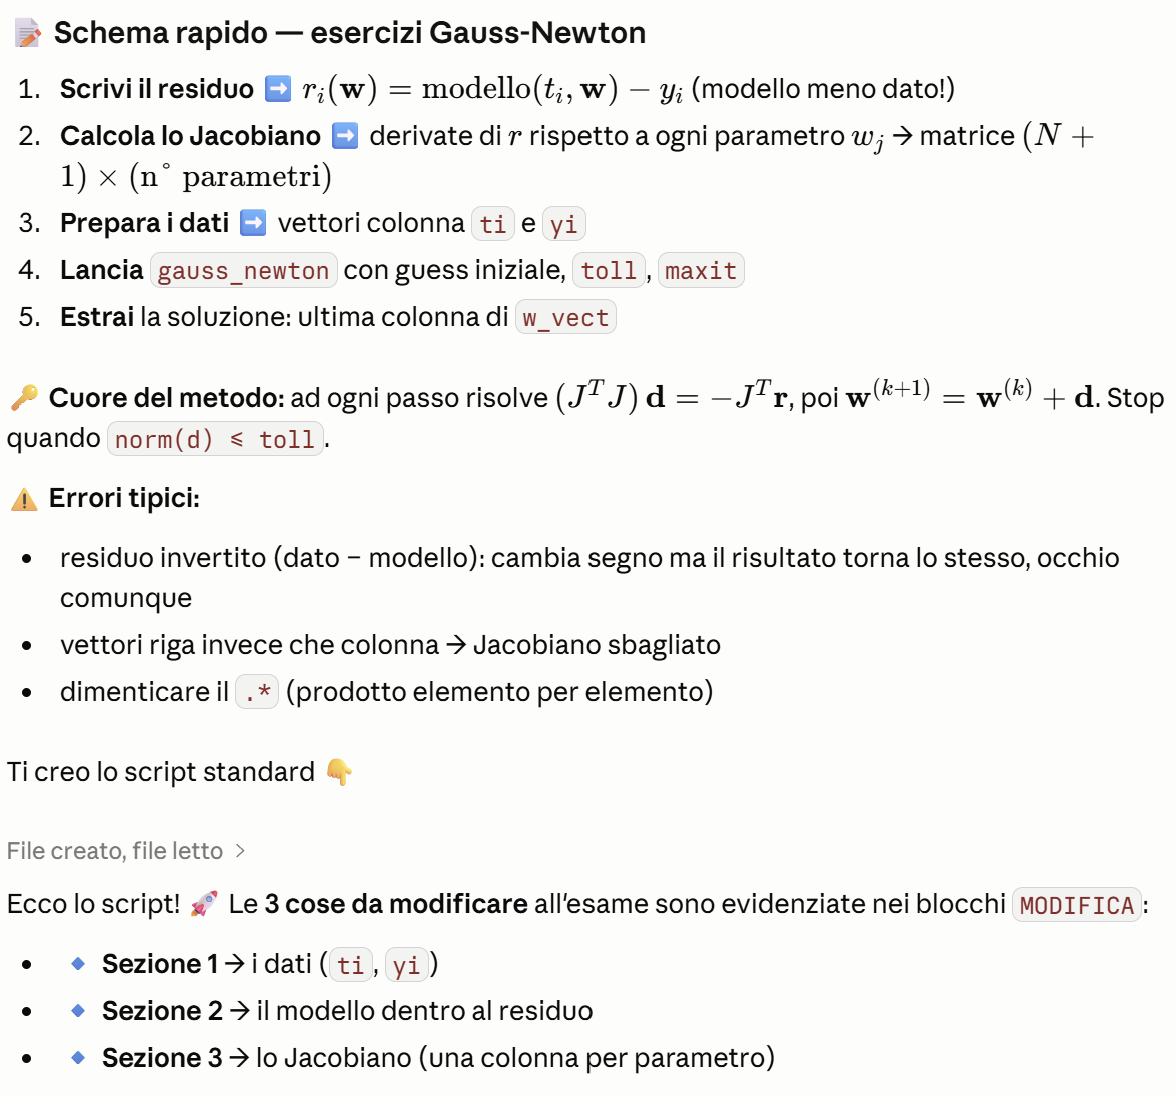

%% =====================================================================
%  TEMPLATE STANDARD - GAUSS-NEWTON (minimi quadrati non lineari)
%  Da modificare velocemente all'esame.
%  Usa la funzione ufficiale: gauss_newton.m
% =====================================================================
%  Problema: trovare w = (w1, w2, ...) che minimizza
%            sum_i ( modello(t_i, w) - y_i )^2
% =====================================================================

clear; clc;

%% ---------------------------------------------------------------------
%  1) DATI  ->  MODIFICA QUI
% ---------------------------------------------------------------------
tf = 10;          % estremo finale (se serve)
N  = 20;          % numero intervalli  ->  i = 0,...,N
ti = (0:N)/N * tf;        % nodi t_i
ti = ti(:);               % FORZA vettore COLONNA (importante!)

% dati y_i  ->  MODIFICA con la formula dei dati dell'esercizio
yi = 3*exp(-ti/3).*( cos(ti) + (1/5)*sin(ti) );
yi = yi(:);               % vettore colonna

%% ---------------------------------------------------------------------
%  2) RESIDUO  ->  r(w) = modello - dato     MODIFICA il modello
% ---------------------------------------------------------------------
%  modello: theta(t) = w1 * exp(w2*t) * cos(w3*t)
r_fun = @(x, y, w) w(1)*exp(w(2)*x).*cos(w(3)*x) - y;

%% ---------------------------------------------------------------------
%  3) JACOBIANO  ->  una COLONNA per ogni parametro w_j
%     ogni colonna = dr/dw_j     dimensione (N+1) x (n_parametri)
% ---------------------------------------------------------------------
%  dr/dw1 =        exp(w2 t) cos(w3 t)
%  dr/dw2 =  w1 t  exp(w2 t) cos(w3 t)
%  dr/dw3 = -w1 t  exp(w2 t) sin(w3 t)
J_fun = @(x, y, w) [ exp(w(2)*x).*cos(w(3)*x), ...
                     w(1)*x.*exp(w(2)*x).*cos(w(3)*x), ...
                    -w(1)*x.*exp(w(2)*x).*sin(w(3)*x) ];

%% ---------------------------------------------------------------------
%  4) PARAMETRI METODO  ->  MODIFICA guess / tolleranza
% ---------------------------------------------------------------------
w0    = [2; -1/2; 1/2];    % guess iniziale (vettore colonna)
toll  = 1e-6;              % tolleranza su norm(d)
maxit = 1000;              % iterazioni massime

%% ---------------------------------------------------------------------
%  5) RISOLUZIONE
% ---------------------------------------------------------------------
[w_vect, Nit] = gauss_newton(ti, yi, r_fun, J_fun, w0, toll, maxit);

w = w_vect(:, end);        % soluzione = ultima colonna

%% ---------------------------------------------------------------------
%  6) RISULTATI
% ---------------------------------------------------------------------
fprintf('\nIterazioni Nit = %d\n', Nit);
fprintf('Parametri stimati w:\n');
disp(w');

%% ---------------------------------------------------------------------
%  (opzionale) CONFRONTO GRAFICO modello vs dati
% ---------------------------------------------------------------------
% tt = linspace(min(ti), max(ti), 500)';
% modello = w(1)*exp(w(2)*tt).*cos(w(3)*tt);
% figure; plot(ti, yi, 'o', tt, modello, '-'); legend('dati','modello');